## Initialize the P, T and b for the Square manually

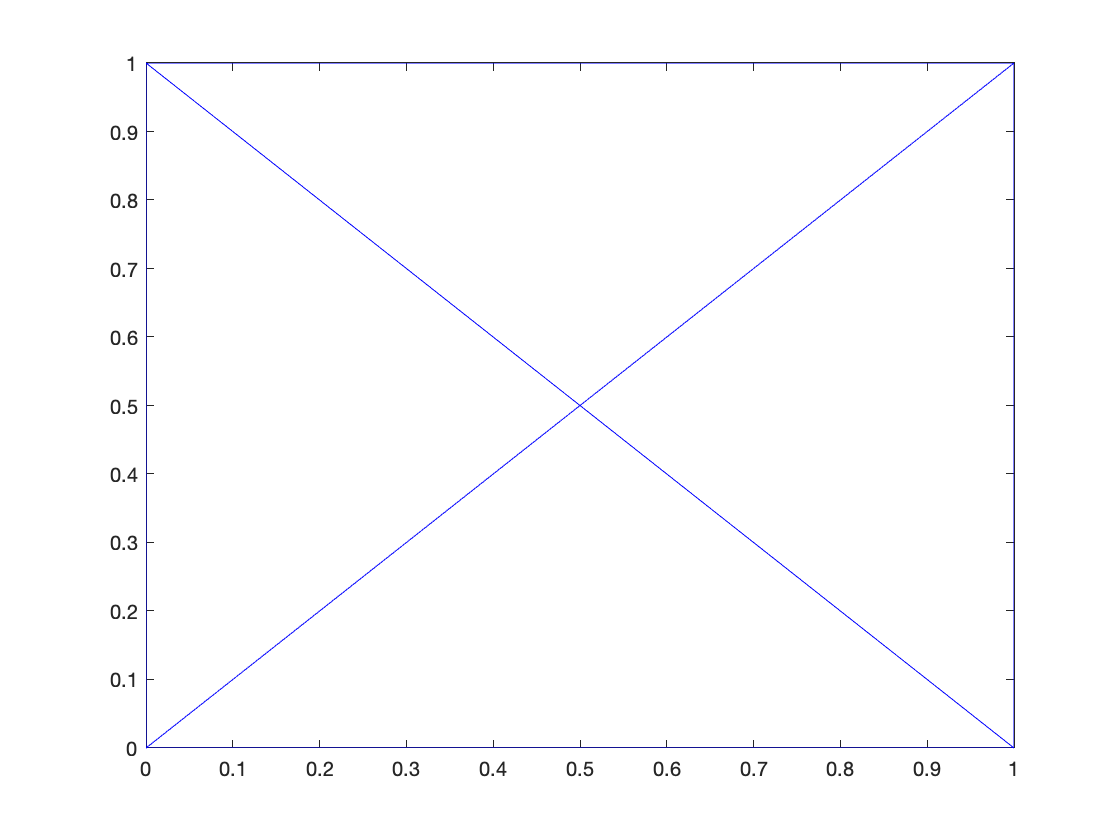

P = [0 0;
     1 0;
     1 1;
     0 1;
     1/2 1/2];
 
T = [1 2 5;
     2 3 5;
     3 4 5;
     4 1 5];

b = [0;
     0;
     0;
     0;
     1];

figure  
vismesh(P, T)

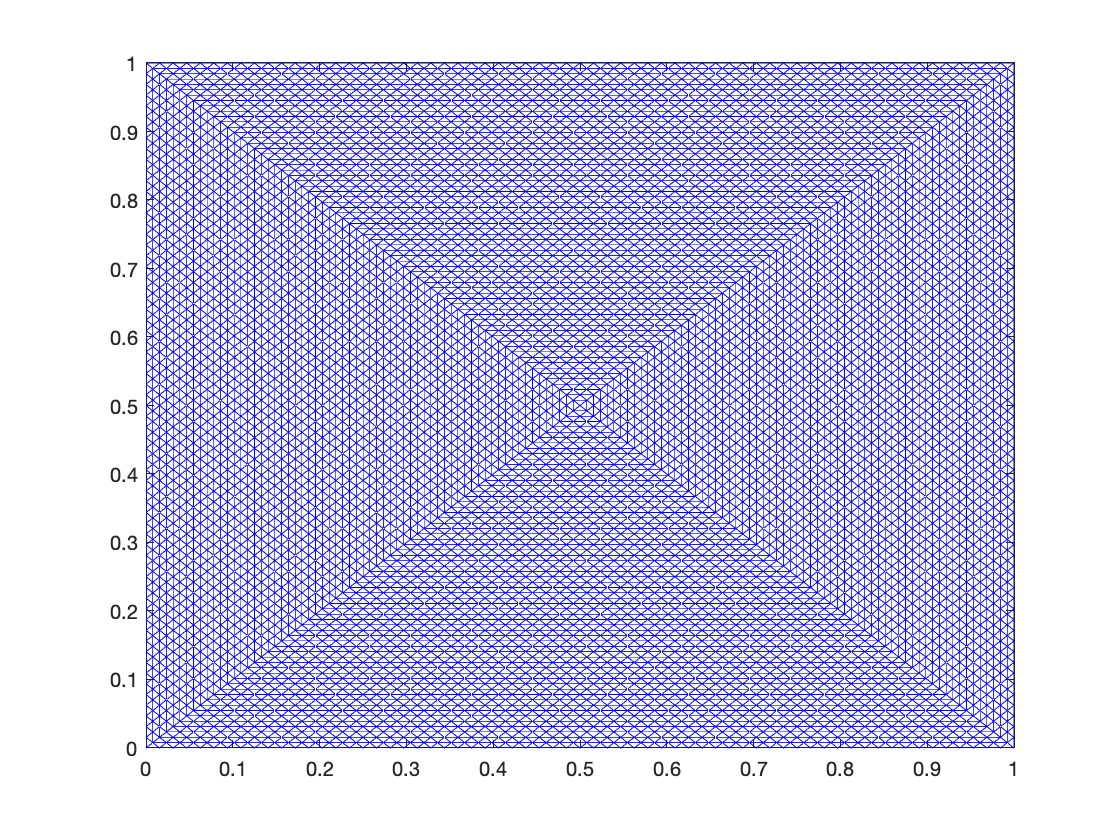

for i = 1:6
[P,T,b] = refine(P,T,b);
end

figure 
vismesh(P, T)

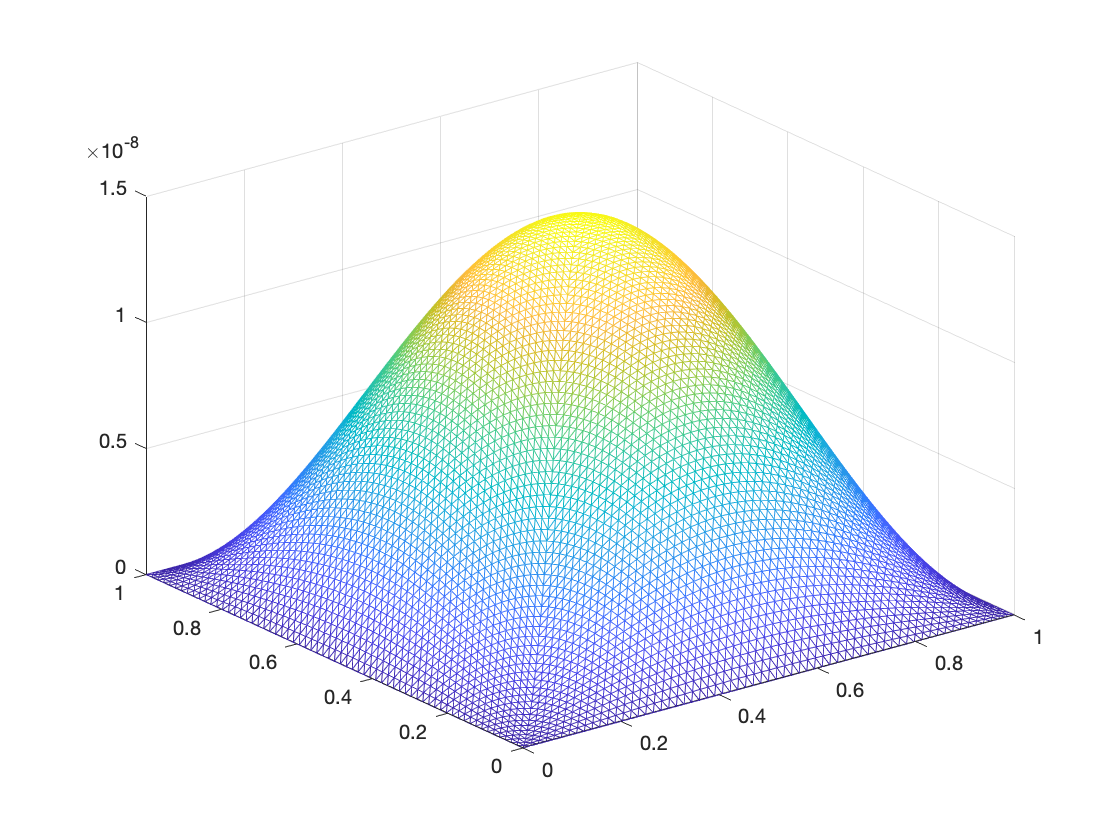

% Solve Poisson's problem with homogeneous Dirichlet boundary condition
rhs_f = @(x, y) 2*pi^2*sin(pi*x)*sin(pi*y); 
S = lhs(P, T, b);
f = rhs(P, T, b, rhs_f);
u = S\f;
figure
visfunc(u, P, T)

## Definition of Functions Part

Visualization of the mesh when the Point list **P**, Element list **T**, and boundary category list **b** are given.

function vismesh(P, T)
    triplot(T, P(:, 1), P(:, 2));
end

Visualization of  function  

function visfunc(u, P, T)
    TO = triangulation(T, P(:,1), P(:,2), u(:));
    trimesh(TO);
end

Refinement function

function [PP, TT, bb] = refine(P, T, b)

    %% Getting Edge lists
    E = {};

    for i = 1:size(P, 1)
        E{end + 1} = {};
    end

    % Iteration over triangles
    for i = 1:size(T, 1)
        % Iteration over triangle points
        for j = 1:3
            ea = T(i, j);
            eb = T(i, mod(j, 3) + 1);

            if ea > eb
                tmp = ea;
                ea = eb;
                eb = tmp;
            end

            E{ea}{end + 1} = eb;
        end

    end

    for i = 1:size(E, 2)
        E{i} = cell2mat(E{i});
        E{i} = unique(E{i});
        E{i} = sort(E{i});
    end

    %% Getting  PP and bb
    PP = [P];
    bb = [b];
    L = {};

    for i = 1:size(E, 2)

        for j = 1:length(E{i})
            pt1 = P(i, :);
            pt2 = P(E{i}(j), :);
            midpt = (pt1 + pt2) ./ 2;

            PP = [PP; midpt];
            L{i, j} = length(PP);

            if b(i) == 0 && b(E{i}(j)) == 0
                bb(L{i, j}) = 0;
            else
                bb(L{i, j}) = 1;
            end

        end

    end

    %% Getting TT
    TT = [T];

    m = [0, 0, 0];

    for i = 1:length(T)

        for j = 1:3
            % finding index
            ea = T(i, j);
            eb = T(i, mod(j, 3) + 1);

            if ea > eb
                % Shall i skip here?
                tmp = ea;
                ea = eb;
                eb = tmp;
            end

            k1 = ea;
            k2 = find(E{ea} == eb);
            m(j) = L{k1, k2};

        end

        TT(4 * i - 3:4 * i, :) = [
                            T(i, 1), m(1), m(3);
                            m(1), T(i, 2), m(2);
                            m(3), m(2), T(i, 3);
                            m(1), m(2), m(3);
                            ];

    end

end

Element stiffness matrices

compute stiffness matrix for each element

X is a matrix consisting of coordinates of three points

each column corresponds to one point in  2D

function A = stiffness(X)
    nabla = [-1, -1;
              1,  0;
              0,  1];
    J = horzcat(X(:,2)-X(:,1),X(:,3)-X(:,1)); 
    A =  1/(2*det(J)) * nabla * inv(J.' * J) * nabla.';
end

Element mass matrices

compute mass matrix for each element

X is a matrix consisting of coordinates of three points

each column corresponds to one point in  2D

function M = mass(X)
    % Compute area of the triangle
    c = cross(vertcat(X(:,3) - X(:,1), [0]), vertcat(X(:,2) - X(:,1), [0]))/2;
    area = norm(c);
    
    M = ones(3) * area/12;
    M(1,1) = area/6;
    M(2,2) = area/6;
    M(3,3) = area/6;
end

LHS

It performs an element based assembly of the stiffness matrix, which should be stored in a sparse matrix format.

function S = lhs(P, T, b)
    S = sparse(size(P,1), size(P,1));
    % Iteration over triangles
    for i = 1:size(T, 1) 
        X = P(T(i,:),:).';
        A = stiffness(X);
        
        % Iteration over all interactions of basis functions
        for j = 1:3
            for k = 1:3
                if b(T(i,j)) ~= 0 && b(T(i,k)) ~= 0
                    S(T(i,j), T(i,k)) = S(T(i,j), T(i,k)) + A(j,k);
                end
            end
        end
    end
    
    % Indentity matrix for points on the boundary 
    for i = 1:length(b)
        if b(i) == 0
            S(i,i) = 1;
        end
    end
end

RHS

Discretisation of the right hand side

function f = rhs(P, T, b, rhs_f)
    M = sparse(size(P,1), size(P,1));
    % Iteration over triangles
    for i = 1:size(T, 1) 
        X = P(T(i,:),:).';
        local_M = mass(X);
        
        % Iteration over all interactions of basis functions
        for j = 1:3
            for k = 1:3
                M(T(i,j), T(i,k)) = M(T(i,j), T(i,k)) + local_M(j,k);
            end
        end
    end
    f = zeros(size(P,1),1);
    for i = 1:size(P,1)
        f(i) = rhs_f(P(i,1), P(i,2));
    end
    f = M * f;
    
    % Boundary condition
    for i = 1:length(b)
        if b(i) == 0
            f(i) = 0;
        end
    end
end